# Model Identification - Project

By: Sebastián Escobar, Marzuq Gallego, Laura Gutiérrez, Santiago Ortiz

clc
clear 
addpath('C:\Users\laura\Documents\2026-2\Control Digital\Funciones')
addpath('C:\Users\laura\Documents\2026-2\Control Digital\Laboratories\Lab III\')

Importing Data Extracted from LabView

data = readtable('inp.xlsx');

head(data); 

     t1      u1     y1       t2      u2    y2     t3      u3    y3
    _____    __    _____    _____    __    __    _____    __    __

        0    10       15        0    0     0         0    0     0 
    0.005    10       15    0.005    0     0     0.005    0     0 
     0.01    10    18.75     0.01    0     0      0.01    0     0 
    0.015    10       15    0.015    0     0     0.015    0     0 
     0.02    10    18.75     0.02    0     0      0.02    0     0 
    0.025    10       15    0.025    0     0     0.025    0     0 
     0.03    10    18.75     0.03    0     0      0.03    0     0 
    0.035    10    18.75    0.035    0     0     0.035    0     0 



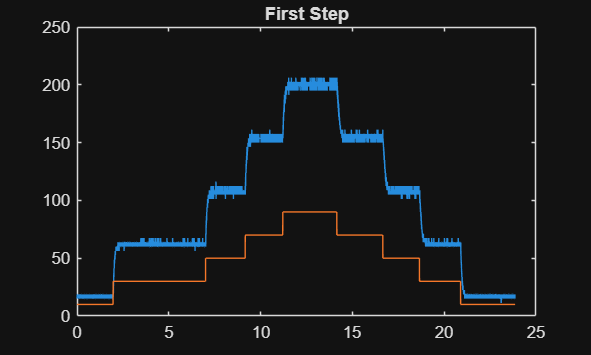

% First Measurement
t1 = data.t1;
u1 = data.u1;
y1 = data.y1; 


% Second Measurement
t2 = data.t2;
u2 = data.u2;
y2 = data.y2; 

% Third Measurement
t3 = data.t3;
u3 = data.u3;
y3 = data.y3; 

figure; 
plot(t1, y1);
hold on; 
plot(t1, u1);
title('First Step');

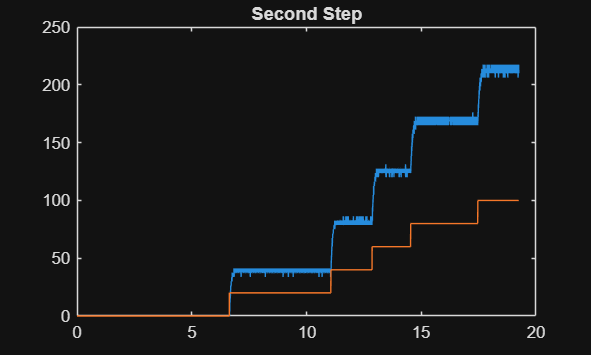


figure; 
plot(t2, y2);
hold on; 
plot(t2, u2);
title('Second Step')

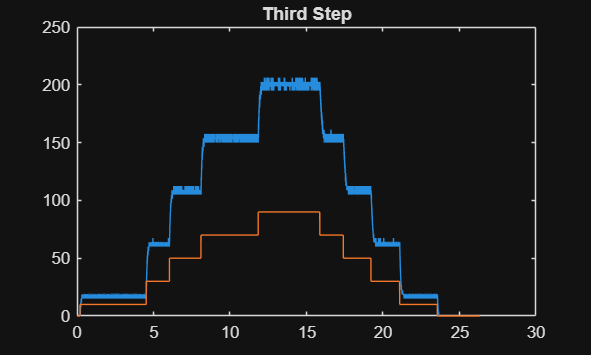


figure; 
plot(t3, y3);
hold on; 
plot(t3, u3);
title('Third Step')

Splitting the data into 3 steps

% Applying the cleaning function to start all steps from t=0
[u1, y1, t1, t_step_1] = ajustarEscalon(u1, y1, t1, fromy=30, toy=50);

Escalón 30 -> 50 ajustado: 433 puntos | t = 0.00 s a 2.16 s (t_abs_inicio = 7.00 s)


[u2, y2, t2, t_step_2] = ajustarEscalon(u2, y2, t2, fromy=40, toy=60);

Escalón 40 -> 60 ajustado: 337 puntos | t = 0.00 s a 1.68 s (t_abs_inicio = 12.86 s)


[u3, y3, t3, t_step_3] = ajustarEscalon

Escalón 30 -> 50 ajustado: 413 puntos | t = 0.00 s a 2.06 s (t_abs_inicio = 6.04 s)


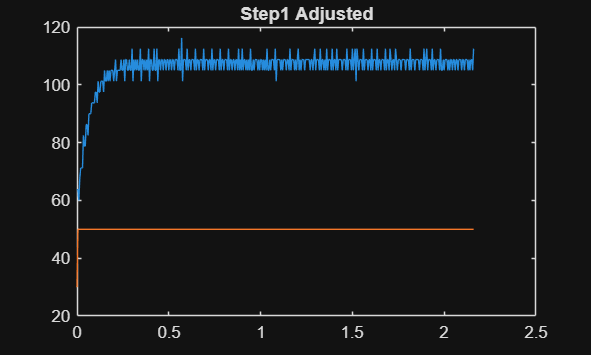


(u3, y3, t3, fromy=30, toy=50);

% Unificar las 3 estructuras independientes en una sola variable 'datos'
datos.step1.u = u1; 
datos.step1.y = y1; 
datos.step1.t = t1; 

datos.step2.u = u2; 
datos.step2.y = y2; 
datos.step2.t = t2; 

datos.step3.u = u3; 
datos.step3.y = y3; 
datos.step3.t = t3; 

%graficar
figure;
plot(datos.step1.t, datos.step1.y)
hold on; 
plot(datos.step1.t, datos.step1.u)
title('Step1 Adjusted')

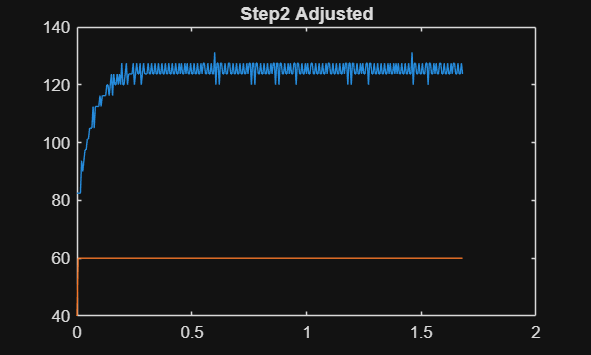


figure;
plot(datos.step2.t, datos.step2.y)
hold on; 
plot(datos.step2.t, datos.step2.u)
title('Step2 Adjusted')

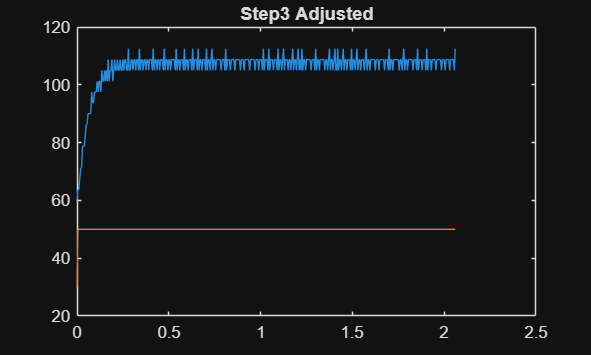


figure;
plot(datos.step3.t, datos.step3.y)
hold on; 
plot(datos.step3.t, datos.step3.u)
title('Step3 Adjusted')

Identification as FOPDT


=== Ajuste FOPDT Sincronizado ===
Ganancia (K):            2.1946
Constante de tiempo (t): 0.0568 s
Tiempo muerto (theta):   0.0092 s
MSE del ajuste:          6.610619
NRMSE:                   0.0457 (4.57% del rango)
Fit Percentage:          62.10%

G_fopdt =
 
                        2.195
  exp(-0.00921*s) * -------------
                    0.05675 s + 1
 
Continuous-time transfer function.


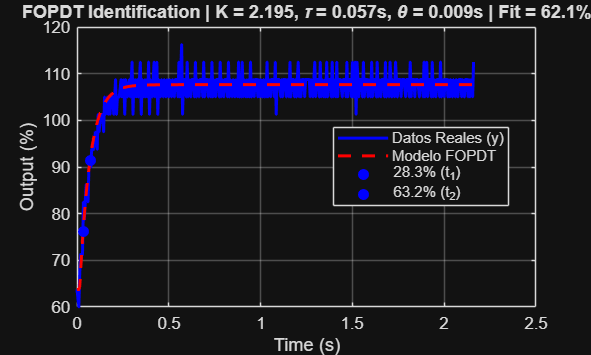

G1 = []; G1S = []; G1SF = []; G2 = []; G2S = []; G2SF = []; G3 = []; G3S = []; G3SF = [];

% Identificar los parámetros para el step 1
[K1, tau1, theta1, G1, mse1] = identificarFOPDT(datos.step1.u, datos.step1.y, datos.step1.t);


=== Ajuste FOPDT Sincronizado ===
Ganancia (K):            2.1375
Constante de tiempo (t): 0.0610 s
Tiempo muerto (theta):   0.0000 s
MSE del ajuste:          5.368805
NRMSE:                   0.0475 (4.75% del rango)
Fit Percentage:          67.14%

G_fopdt =
 
      2.138
  -------------
  0.06096 s + 1
 
Continuous-time transfer function.


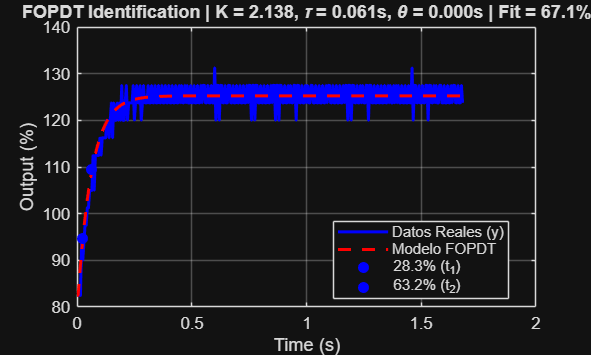


% Identificar para el step 2 (si existe)
if isfield(datos, 'step2')
    [K2, tau2, theta2, G2, mse2] = identificarFOPDT(datos.step2.u, datos.step2.y, datos.step2.t);
end


=== Ajuste FOPDT Sincronizado ===
Ganancia (K):            2.4062
Constante de tiempo (t): 0.0594 s
Tiempo muerto (theta):   0.0000 s
MSE del ajuste:          4.757470
NRMSE:                   0.0415 (4.15% del rango)
Fit Percentage:          67.16%

G_fopdt =
 
      2.406
  -------------
  0.05941 s + 1
 
Continuous-time transfer function.


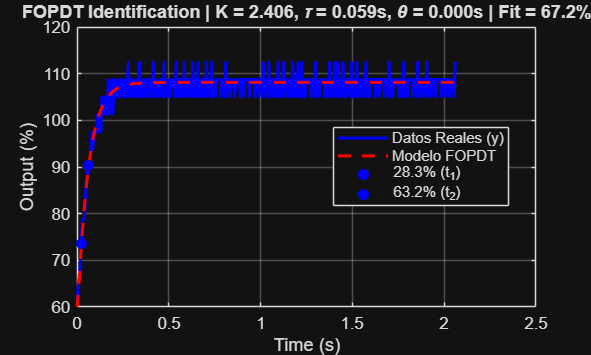


% Identificar para el step 3 (si existe)
if isfield(datos, 'step3')
    [K3, tau3, theta3, G3, mse3] = identificarFOPDT(datos.step3.u, datos.step3.y, datos.step3.t);
end

Identification as SOPDT


=== SOPDT Identification  ===
Tiempos detectados: t1=0.0139s, t2=0.0330s, t3=0.0908s | x=0.3570
Ganancia (K):           2.1946
Amortiguamiento (zita): 3.2636
Frecuencia nat. (wn):   102.4210 rad/s
Tau 1:                  0.0622 s
Tau 2:                  0.0015 s
Tiempo muerto (theta):  0.0000 s
MSE del ajuste:         6.702606
NRMSE:                  0.0460 (4.60% del rango)
Fit Percentage:         61.84%
--------------------------------------------------------


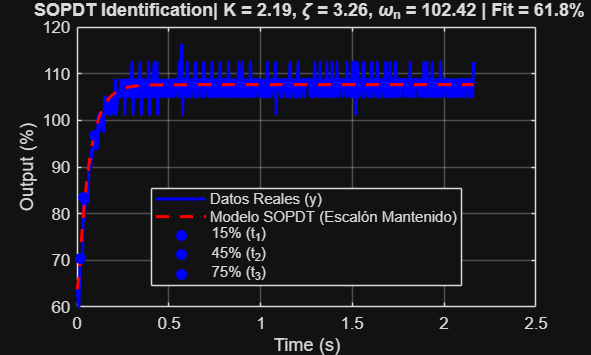

% Identificar los parámetros para el step 1
[K1S, zita1S, wn1S, tau11S, tau21S, theta1S, G1S, G1SF, mse1S] = identificarSOPDT(datos.step1.u, datos.step1.y, datos.step1.t);

G1S


G1S =
 
          2.302e04
  ------------------------
  s^2 + 668.5 s + 1.049e04
 
Continuous-time transfer function.


G1SF


G1SF =
 
              2.195
  -----------------------------
  9.533e-05 s^2 + 0.06373 s + 1
 
Continuous-time transfer function.



% Identificar para el step 2 (si existe)
if isfield(datos, 'step2')
    [K2S, zita2S, wn2S, tau12S, tau22S, theta2S, G2S, G2SF, mse2S] = identificarSOPDT(datos.step2.u, datos.step2.y, datos.step2.t);
end

Error using identificarSOPDT (line 105)
No se puede utilizar este método: El factor de amortiguamiento calculado (zita = 0.6339) es menor que 1 (el sistema no es sobreamortiguado).

G2S
G2SF


% Identificar para el step 3 (si existe)
if isfield(datos, 'step3')
    [K3S, zita3S, wn3S, tau13S, tau23S, theta3S, G3S, G3SF, mse3S] = identificarSOPDT(datos.step3.u, datos.step3.y, datos.step3.t);
end
G3S
G3SF


Comparing all models

% Modelos FOPDT agrupados
modelos_FOPDT = {G1, G2, G3}; 

% Modelos SOPDT agrupados
modelos_SOPDT = {G1S, G2S, G3S}; 

% === GRAFICACIÓN COMPARATIVA DESDE EL ORIGEN (0,0) ===

% 1. Detectar automáticamente cuántos escalones hay en 'datos'
campos = fieldnames(datos);
num_steps = sum(startsWith(campos, 'step'));

% 2. Colores por Step: Step 1 (Azul), Step 2 (Rojo), Step 3 (Verde)
colores_steps = {'b', 'r', 'g'};

figure('Name', 'All Models COmparison', 'NumberTitle', 'off');
hold on; grid on;

for i = 1:num_steps
    nombre_step = sprintf('step%d', i);
    if ~isfield(datos, nombre_step), continue; end

    % --- A. Extraer datos del escalón ---
    u_rec = datos.(nombre_step).u(:);
    y_rec = datos.(nombre_step).y(:);
    t_rec = datos.(nombre_step).t(:);

    % Offsets y normalización temporal al origen
    t_sim = t_rec - t_rec(1);
    y0 = y_rec(1); 
    u0 = u_rec(1);

    % --- B. Detección del escalón de subida y cálculo de delta_u ---
    du = [0; abs(diff(u_rec))];
    idx_step = find(du > 0.1 * max(du), 1, 'first');
    if isempty(idx_step), idx_step = 1; end

    % Detección de caída para hallar u_ss en la primera zona activa
    du_real = [0; diff(u_rec)];
    idx_caida = find(du_real(idx_step+1:end) < -0.1 * max(du), 1, 'first');
    if ~isempty(idx_caida)
        idx_fin_u = idx_step + idx_caida - 1;
    else
        idx_fin_u = length(u_rec);
    end

    num_ss_u = max(3, round((idx_fin_u - idx_step) * 0.2));
    idx_ss_inicio = max(idx_step + 1, idx_fin_u - num_ss_u);
    u_ss = mean(u_rec(idx_ss_inicio:idx_fin_u));

    delta_u = u_ss - u0;
    if abs(delta_u) < 1e-5, delta_u = max(u_rec) - min(u_rec); end

    % Generar Escalón Mantenido Sintético 
    u_escalon_mantenido = zeros(size(t_sim));
    u_escalon_mantenido(idx_step:end) = delta_u;

    % Color e índices de marcadores para esta iteración
    color_step = colores_steps{mod(i-1, length(colores_steps)) + 1};
    idx_markers = round(linspace(1, length(t_sim), 15));

    % --- D. Graficar Medición Real desplazada al origen (y - y0) ---
    plot(t_sim, y_rec - y0, '-', 'Color', color_step, 'LineWidth', 1.2, ...
        'DisplayName', sprintf('Real Step %d', i));

    % --- E. Simular y Graficar FOPDT (--o) con Escalón Mantenido ---
    if i <= length(modelos_FOPDT) && ~isempty(modelos_FOPDT{i})
        G_f = modelos_FOPDT{i};
        y_sim_f = lsim(G_f, u_escalon_mantenido, t_sim); 

        plot(t_sim, y_sim_f, '--o', 'Color', color_step, 'LineWidth', 1.5, ...
            'MarkerIndices', idx_markers, 'MarkerSize', 5, ...
            'DisplayName', sprintf('FOPDT Step %d', i));
    end

    % --- F. Simular y Graficar SOPDT (-*) con Escalón Mantenido ---
    if i <= length(modelos_SOPDT) && ~isempty(modelos_SOPDT{i})
        G_s = modelos_SOPDT{i};
        y_sim_s = lsim(G_s, u_escalon_mantenido, t_sim); 

        plot(t_sim, y_sim_s, '-x', 'Color', color_step, 'LineWidth', 1.5, ...
            'MarkerIndices', idx_markers, 'MarkerSize', 5, ...
            'DisplayName', sprintf('SOPDT Step %d', i));
    end
end

% --- Formato Final ---
xlabel('Time (s)');
ylabel('Output (%)');
title('All Systems Comparison');
legend('Location', 'best', 'NumColumns', num_steps);
set(gca, 'Box', 'off', 'TickDir', 'out');

Comparing best two models

% === CONFIGURACIÓN DE MODELOS A COMPARAR ===
G_fopdt = G2; % Modelo de primer orden
G_sopdt = G2S; % Modelo de segundo orden
magnitud = 30; % Magnitud del escalón deseado

figure('Name', 'Comparación Directa FOPDT vs SOPDT', 'NumberTitle', 'off');
grid on; hold on;

% 1. Simular y graficar la respuesta al escalón del modelo FOPDT (--o)
[y_f, t_f] = step(G_fopdt);
plot(t_f, y_f * magnitud, '--o', 'LineWidth', 1.6, ...
    'MarkerIndices', round(linspace(1, length(t_f), 12)), 'MarkerSize', 5, ...
    'DisplayName', 'Modelo FOPDT (1er Orden)');

% 2. Simular y graficar la respuesta al escalón del modelo SOPDT (-*)
[y_s, t_s] = step(G_sopdt);
plot(t_s, y_s * magnitud, '-*', 'LineWidth', 1.6, ...
    'MarkerIndices', round(linspace(1, length(t_s), 12)), 'MarkerSize', 5, ...
    'DisplayName', 'Modelo SOPDT (2do Orden)');

% --- Formato Final ---
xlabel('Tiempo (s)');
ylabel('Respuesta a la Salida y(t)');
title(sprintf('Comparación de Modelos (Escalón de Magnitud %d)', magnitud));
legend('Location', 'best');
set(gca, 'Box', 'off', 'TickDir', 'out');

Comparing the selected model and the model obtained from the same sample but with system identification

s = tf('s');
Ganalytical = G3; 
GsystemIdentification = exp(-35.98*s)*0.40946/(11.368*s + 1);
amp = 0.7;
figure;
step(amp*Ganalytical, amp*GsystemIdentification)
title('Comparison for identification methods for the FOPDT for step 3')
legend('Analytical Model', 'System identification model');

Identifying the appropriate sampling time chosen a tf from the identified options

TF = G3;

disp('----------------------------------------------------------');
disp('Planta de Prueba Identificada G(s):');
TF

% 2. Aplicación de los 3 Métodos de Muestreo

% Método A: Bandwidth (-3 dB)
[ts_min_bw, ts_max_bw, ws] = identificarSamplingTime(feedback(TF, 1));

% Método B: Tau Equivalente (Polo Dominante)
[ts_min_tau, ts_max_tau, tau_eq] = identificarSamplingTimeTauEq(feedback(TF, 1));

% Método C: Tiempo de Asentamiento (Settling Time)
[ts_min_st, ts_max_st, t_settling] = identificarSamplingTimeSettling(TF);


% 3. Tabla Comparativa de Rangos
metodos = {'Bandwidth (-3dB)'; 'Tau Equivalente'; 'Settling Time (2%)'};
Ts_minimos = 1000*[ts_min_bw; ts_min_tau; ts_min_st];
Ts_maximos = 1000*[ts_max_bw; ts_max_tau; ts_max_st];

tabla_resultados = table(metodos, Ts_minimos, Ts_maximos, ...
    'VariableNames', {'Metodo', 'Ts_Min_ms', 'Ts_Max_ms'});

fprintf('\n=== RESUMEN COMPARATIVO DE RANGOS DE MUESTREO ===\n');
disp(tabla_resultados);


Discretization of the System 

G_ol = G3;
tfinal = 400;  

% Ver la respuesta Frecuencial el Lazo Abierto
figure; 
% bode(feedback(G_ol, 1))

ts_bw = 6.05;
ts_et = 2.35;
ts_st = 2.35;

dis_bw = c2d(G_ol, ts_bw, 'zoh')
dis_et = c2d(G_ol, ts_et, 'zoh')
dis_st = c2d(G_ol, ts_st, ['z14' ...
    'oh'])
amp = 0.7;


% Comparing all 
figure;
step(amp*G_ol, amp*dis_bw, amp*dis_et, amp*dis_st, tfinal)
legend('Open Loop', 'Bandwidth Criteria', 'Estimated tau Criteria', 'Settling Time Criteria');

Finding the Range of the proportional controller using the Jury Stability Test

GHz = dis_bw; 
[rango_K, es_estable] = controllerJury(GHz);

Comparing K Values

%% Discrete-Time Proportional Controller Analysis
% Define the sample time and the open-loop discrete transfer function G(z)
Ts = 6.05; 
z = tf('z', Ts);

% Define First-Order Plant (Placeholder from previous code)
G = z^-6 *((0.005829*z+ 0.1605) / (z - 0.5916));

%% Define Proportional Gains (K)
% Updated K values to match image_060919.png
K_inside = [-2.4, 1.5, 3.0355]; 
K_outside = 3.5;         
K_test = [K_inside, K_outside];

%% Initialize Arrays for Transient Metrics
Rise_Time = zeros(length(K_test), 1);
Settling_Time = zeros(length(K_test), 1);
Overshoot_Percent = zeros(length(K_test), 1);
Peak_Value = zeros(length(K_test), 1);

%% Simulate and Plot Step Responses
figure('Name', 'Discrete Closed-Loop Step Responses');
hold on;
grid on;

% Generate distinct colors for the plot lines
colors = lines(length(K_test)); 

% Define the step amplitude
step_amp = 0.7;

for i = 1:length(K_test)
    K = K_test(i);

    % Closed-loop transfer function: T(z) = K*G(z) / (1 + K*G(z))
    T = feedback(K * G, 1);

    % 1. Simulate the standard unit step response
    [y_unit, t] = step(T, 2000); 

    % 2. Scale the response for a step amplitude of 0.7
    y = y_unit * step_amp;

    % 3. Extract and Store Transient Characteristics from the scaled data
    info = stepinfo(y, t);
    Rise_Time(i) = info.RiseTime;
    Settling_Time(i) = info.SettlingTime;
    Overshoot_Percent(i) = info.Overshoot;
    Peak_Value(i) = info.Peak;

    % 4. Plot results
    if K == K_outside
        plot(t, y, '--', 'Color', colors(i,:), 'LineWidth', 2, ...
            'DisplayName', sprintf('K = %g (Outside Range)', K));
    else
        plot(t, y, 'Color', colors(i,:), 'LineWidth', 1.5, ...
            'DisplayName', sprintf('K = %g (Inside Range)', K));
    end
end

% Add a reference line to visualize the 0.7 target
plot(t, step_amp * ones(size(t)), 'k:', 'LineWidth', 1.5, 'DisplayName', 'Reference (0.7)');

% Format the plot
title('Discrete Closed-Loop Step Response');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('Location', 'best');
hold off;

%% Display Transient Characteristics Table
K_Value = K_test';
TransientMetrics = table(K_Value, Rise_Time, Settling_Time, Overshoot_Percent, Peak_Value);
disp('Transient Response Characteristics:')
disp(TransientMetrics)

Routh Criteria

GHz = dis_bw; 
[rango_K, es_estable] = controllerRouth(GHz, -2.4);